% """  Fixed Parameters   """ %
s = tf('s');
g = 9.82;

% """  Drone Transfer   """ %
G = g / s^2; % Drone - Transfer function

% """  Parameters  """ %
OS = 20; % Overshoot (%)
T_s = 10; % Setting time (s)

zeta = - log(OS / 100) / sqrt(pi^2 + log(OS / 100)^2) % Damping ratio

zeta = 0.4559

omega_n = 4 / (zeta * T_s) % Natrual frequency

omega_n = 0.8773


pole_d_plus  = - zeta * omega_n + omega_n * sqrt(zeta^2 - 1) % Desired positive pole

pole_d_plus = -0.4000 + 0.7808i

G_at_pole = evalfr(G,pole_d_plus) % G(pole_d_plus) - Corelation between the desired poles and current poles

G_at_pole = -7.4542 +10.3554i

phi = pi - atan2(imag(G_at_pole),real(G_at_pole)) % Zero angle to G at desired pole (rad)

phi = 0.9469


z_c = real(pole_d_plus) + imag(pole_d_plus) / tan(phi) % a = b / tan(angle)

z_c = 0.1620


K = 1/(abs((pole_d_plus - z_c)*G_at_pole)) % Derivitive gain

K = 0.0815

D = K * (s + z_c)


D =
 
  0.08147 s + 0.0132
 
Continuous-time transfer function.
Model Properties



KP = K * z_c

KP = 0.0132

KD = K

KD = 0.0815

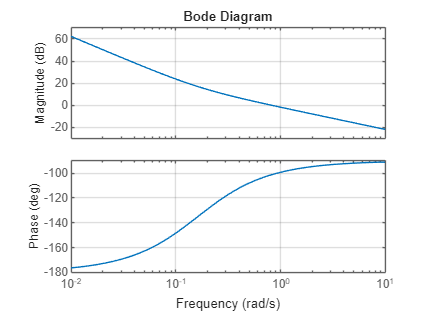


% """  System   """ %
OL = G * D;

% Bode plot
bode(OL)
grid on


%Plot step respons
CL = feedback(OL,1)


CL =
 
     0.8 s + 0.1296
  --------------------
  s^2 + 0.8 s + 0.1296
 
Continuous-time transfer function.
Model Properties


%t = linspace(0, 10, 1000);
t = linspace(0,10,10000)

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


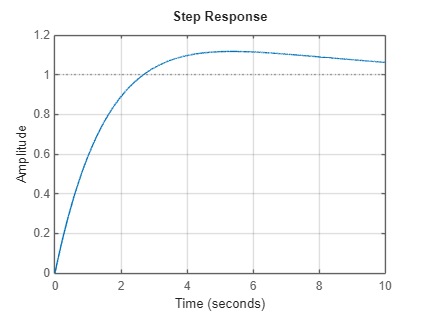

step(CL,t);
grid on;

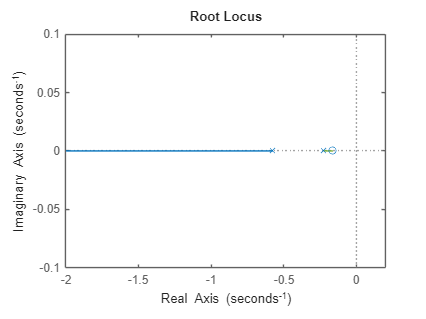

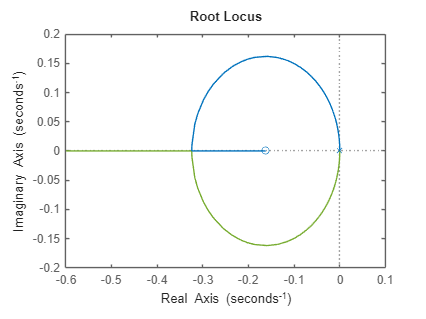


rlocus(CL)


stepinfo(CL)

ans = struct with fields:
         RiseTime: 1.9198
    TransientTime: 15.3523
     SettlingTime: 15.3523
      SettlingMin: 0.9070
      SettlingMax: 1.1172
        Overshoot: 11.7245
       Undershoot: 0
             Peak: 1.1172
         PeakTime: 5.2928




%Ideal system
ideal_sys = tf(omega_n^2, [1, 2*zeta*omega_n, omega_n^2]);
disp('Ideal system: ');

Ideal system: 


stepinfo(ideal_sys)

ans = struct with fields:
         RiseTime: 1.7762
    TransientTime: 9.4922
     SettlingTime: 9.4922
      SettlingMin: 0.9334
      SettlingMax: 1.2000
        Overshoot: 19.9997
       Undershoot: 0
             Peak: 1.2000
         PeakTime: 4.0295
